# DynaLearn: DynaSim's learning, memory and intelligent modeling extention tutorial

@HNXJ: ->For ease of use, previously created DL demo is located in 'models/dlDemoPredictivePFC/'. 

You can still create your own DL model based on your dynasim struct.

## Getting started

DynaLearn is an extention for structured use of dynasim. In this tutorial, we will use it to train a dynasim model. 

For start, you need to make a dynasim model (struct). Here are the examples:

### Create Dynasim struct (situational)

close all;clear;clc;
Ne = 20;Ni = 4;Nio = 10;noise_rate = 13;

 If you dont have a saved class file, uncomment one of these lines and remake a DynaLearn model in the next section.

% s = NeoCortex(Ne, Ni, Nio, noise_rate); % Basic Neocortex model
% s = dlDemoPING(5, 1, 2, noise_rate); % Basic PING model
% s = dlDemoPredictivePFC(Ne, Ni, Nio, noise_rate); % PFC model based on predictive coding

## DynaLearn class

As dynaLearn requires a dynasim struct model or a previously saved DynaLearn model, we should create or load one.

Here we've provided both options for example:

## Create new DL class

Using struct 's' which contains your Dynasim struct, call DynaLearn constructor. As it will make 'mex' file for saving runtime later, it may take several minutes to make one. You can save and load your class later.

m = DynaLearn(s, 'models/dlYourModelName'); % ~ takes several minutes

Creating Dyna model object ... 
DL object loaded from DynaSim/models/dlBaseModel 
Params.mat file loaded from DynaSim/models/dlBaseModel 

Reinitialized.
DynaLearn model created.


m.dlSave(); % Save class to its workbench (here it will be 'models/dlYourModelName')

DL object loaded from models/dlDemoPredictivePFC 
Params.mat file loaded from models/dlDemoPredictivePFC 

Reinitialized.


#### Dont forget to save your model!

## Load DynaLearn Class (previously saved file is required)

In case that you want to just run a basic test or you have a previously saved DynaLearn class, continue from here.

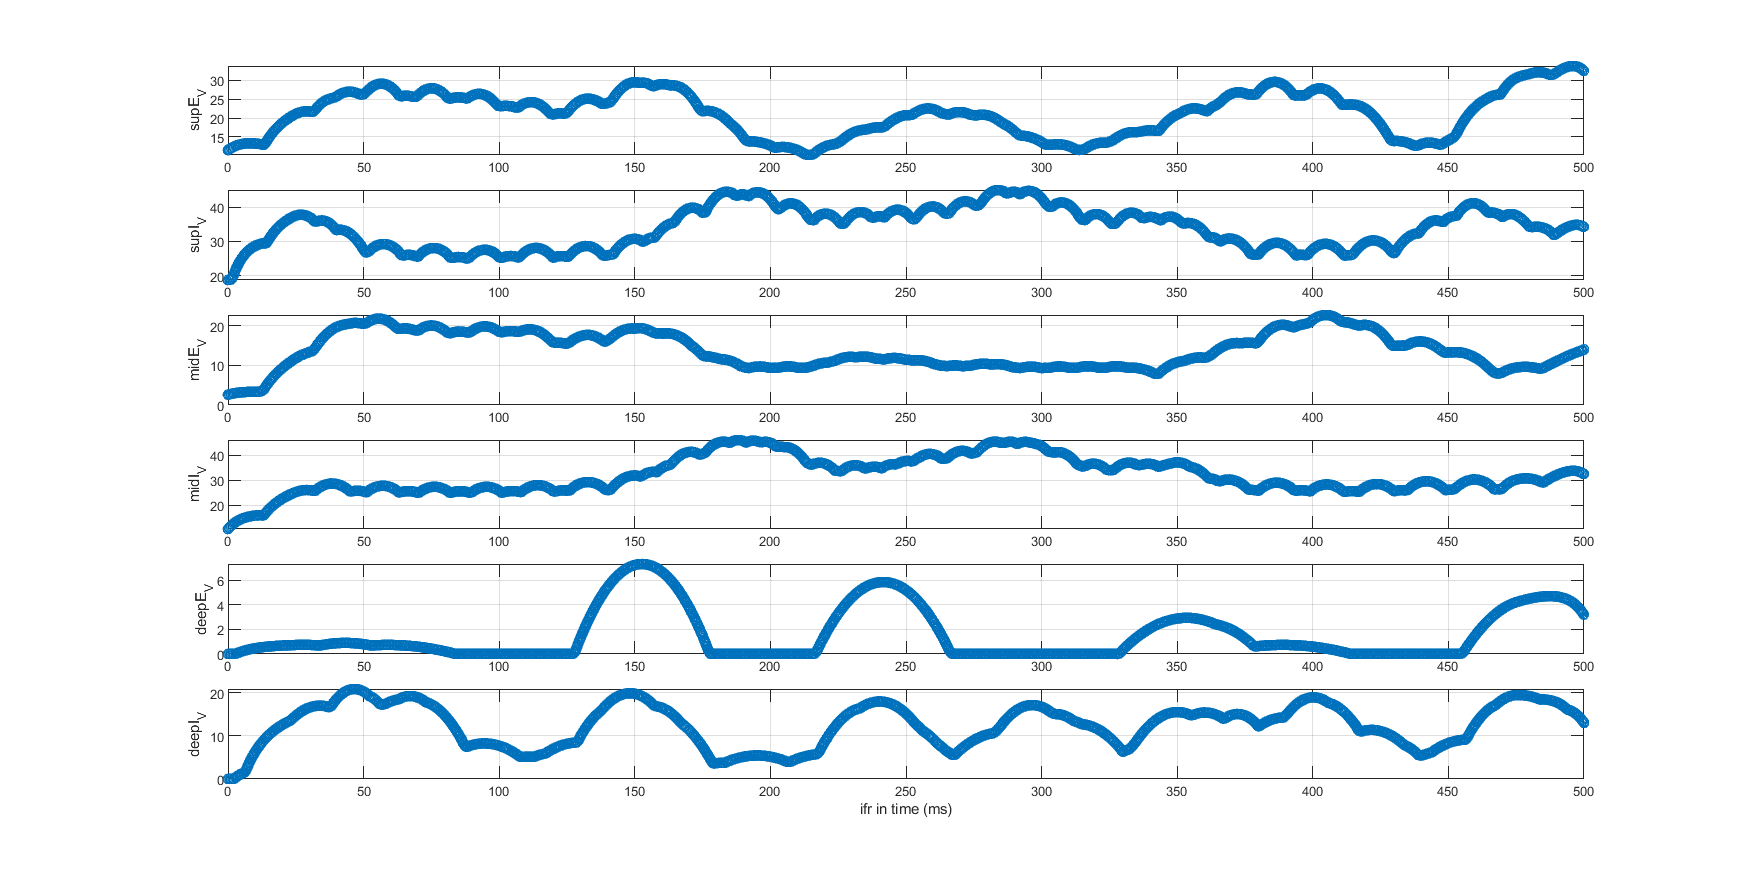

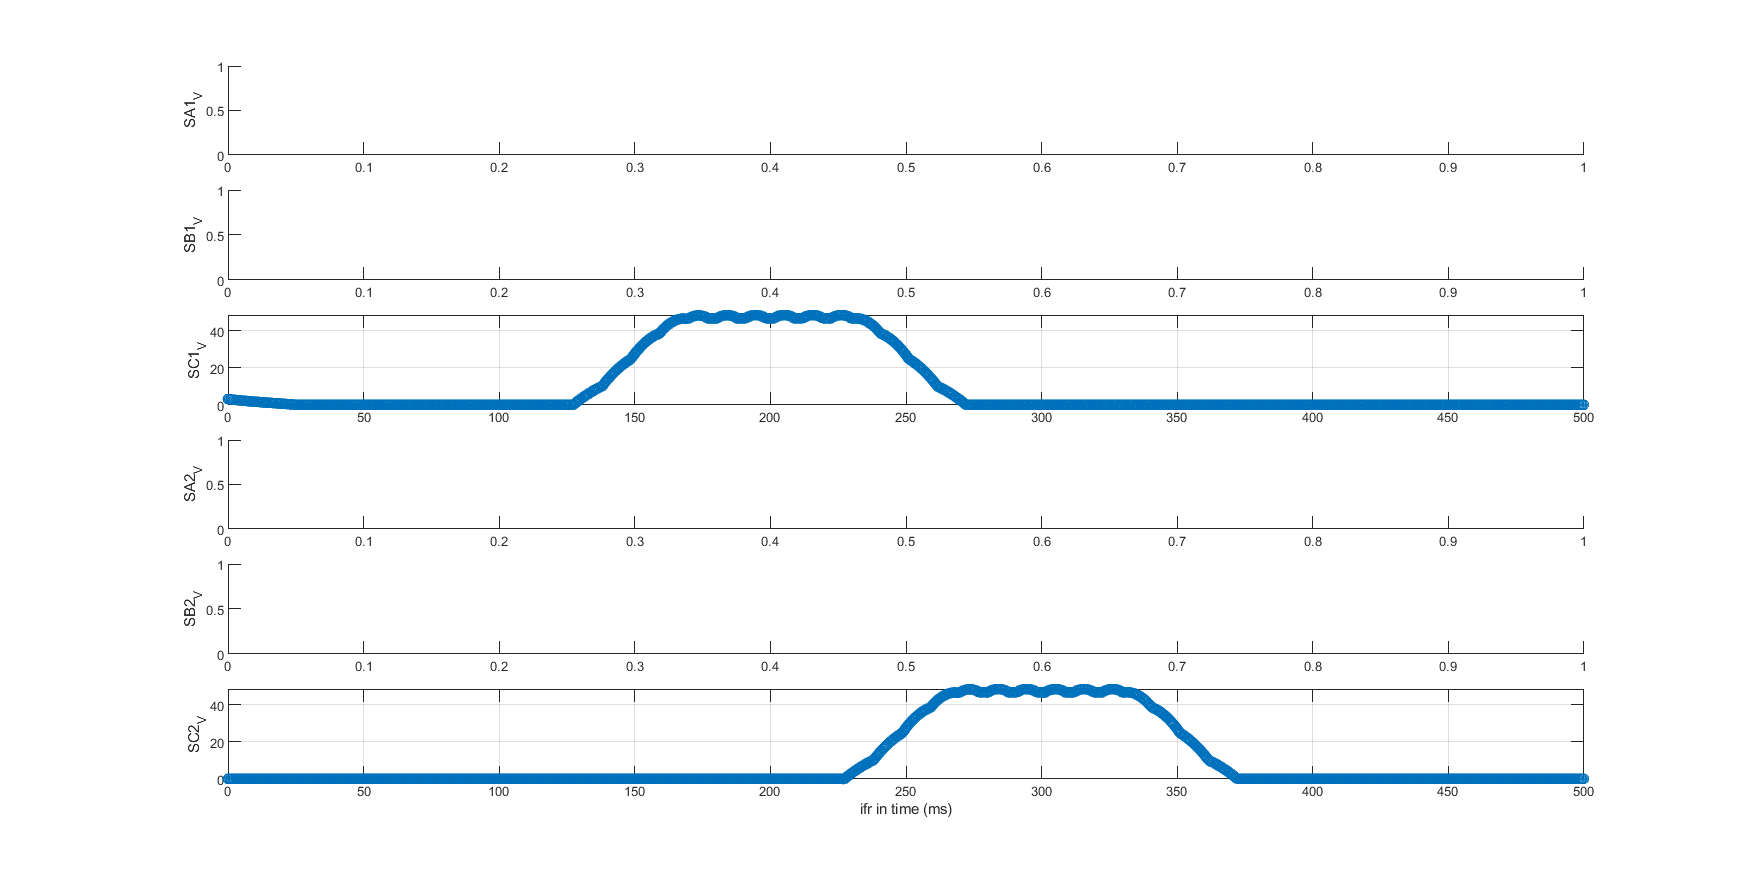

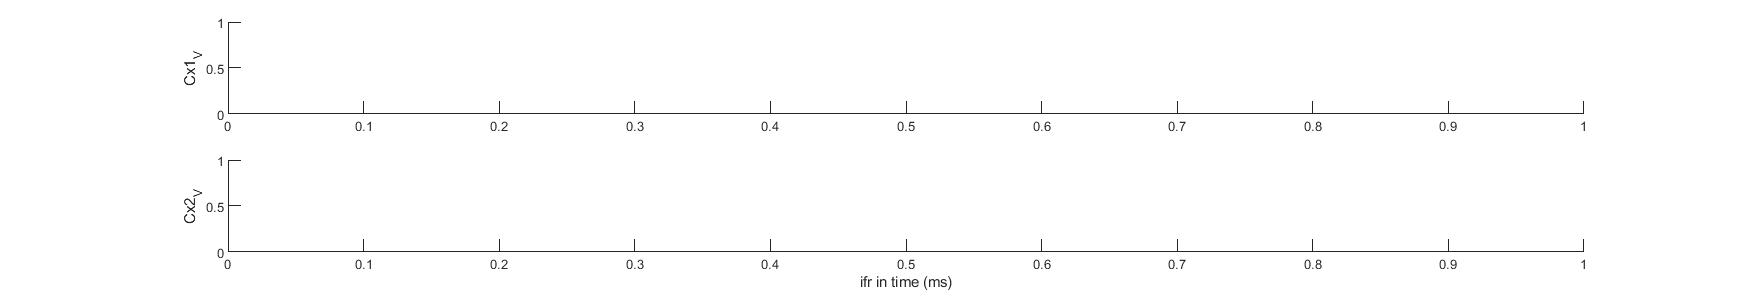

m = DynaLearn(); % Create basic instance of DynaLearn
m = m.dlLoad('models/dlDemoPredictivePFC'); % Load your previously saved copy or demo file

## Simulate and plot example

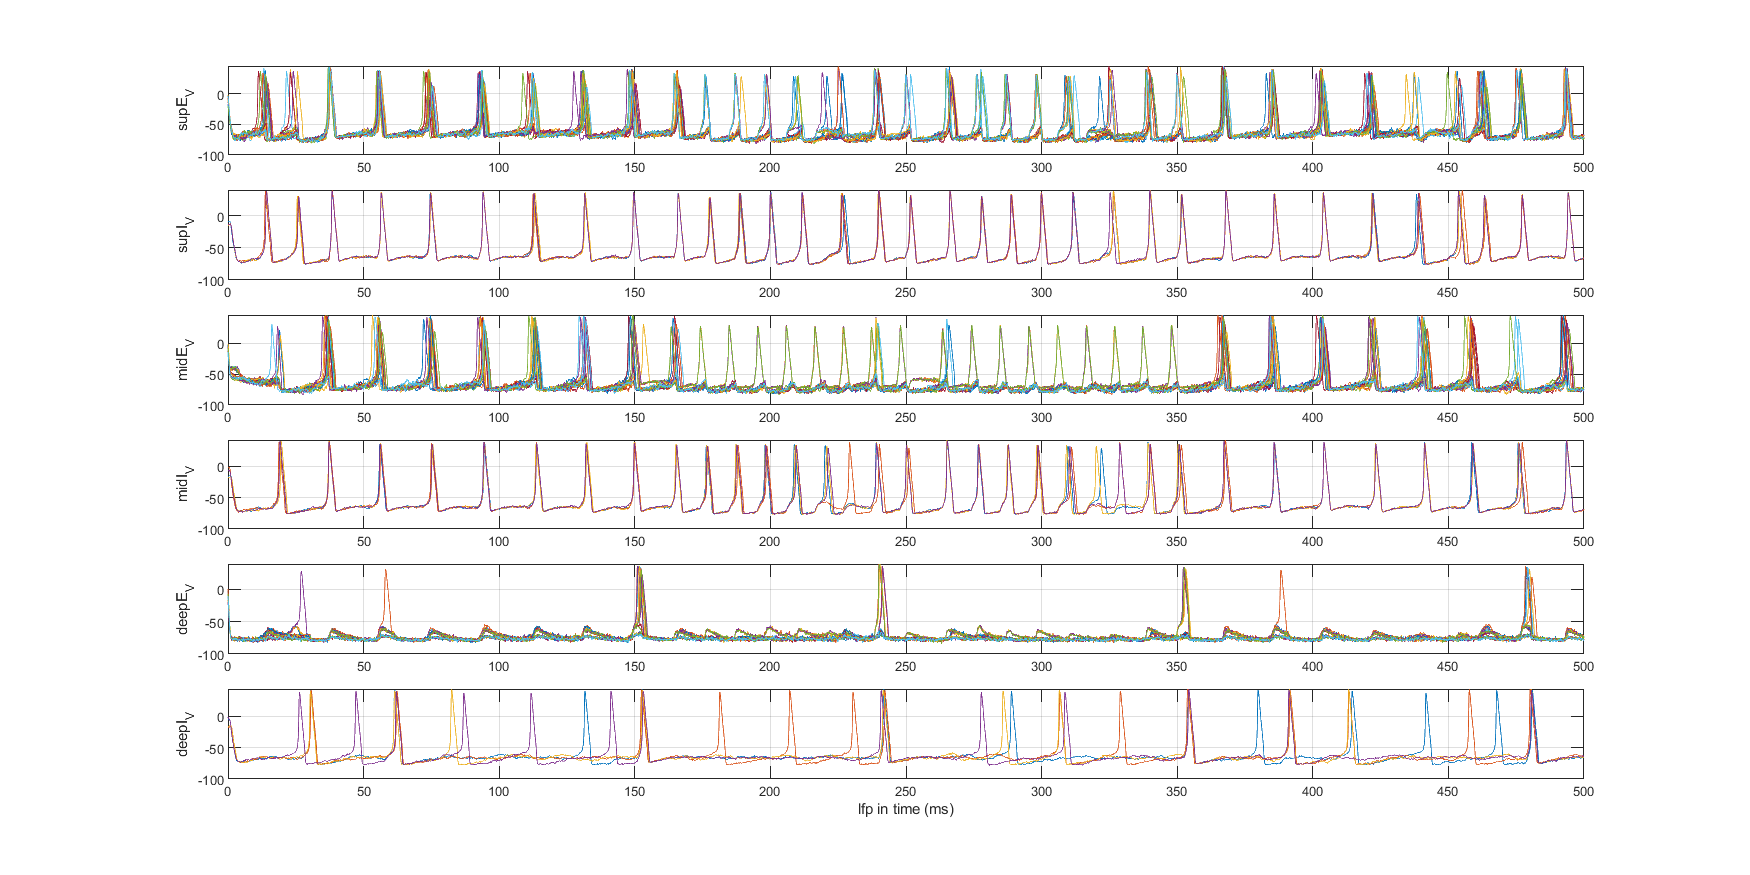

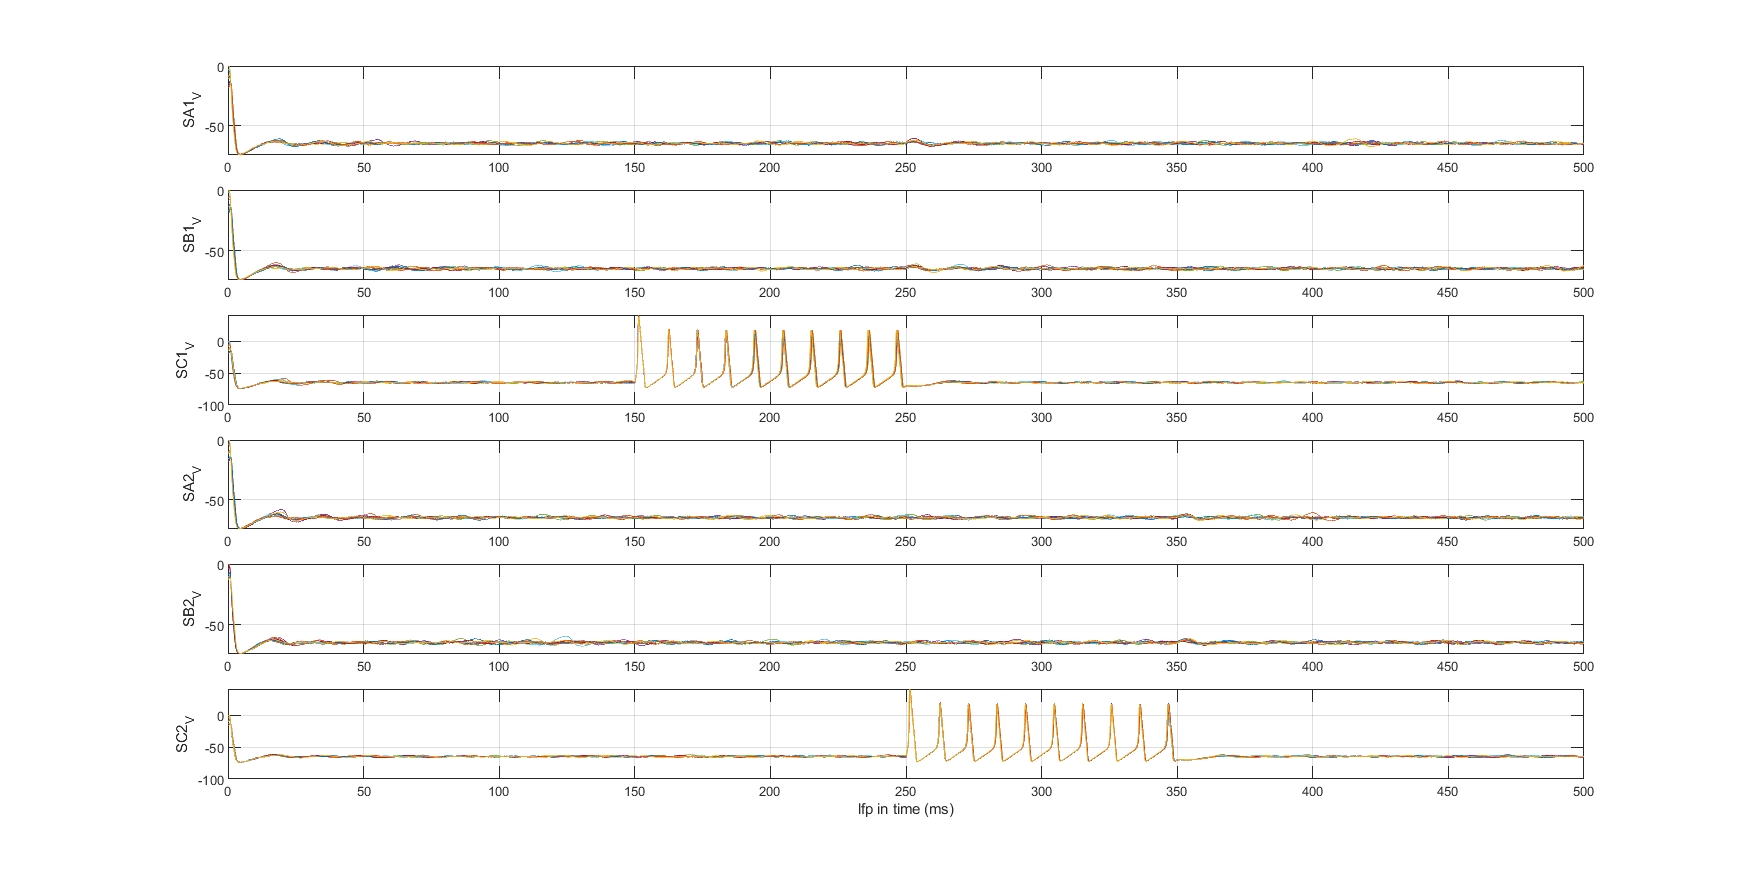

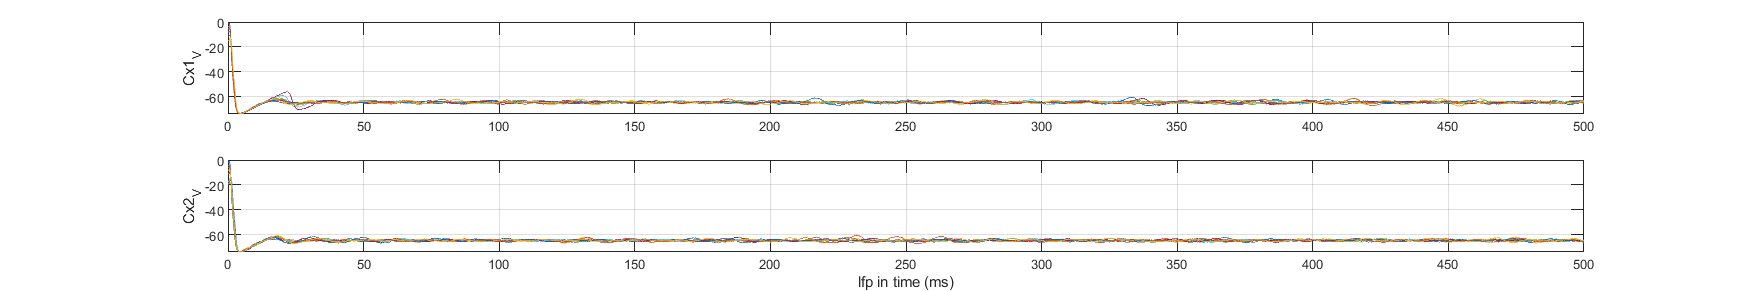

m.dlSimulate(); % (optional) simulate it , ~ seconds runtime

m.dlPlotAllPotentials('ifr'); % Plot all potential (voltages) as IFR plots ('ifr') or LFP ('lfp').
m.dlPlotAllPotentials('lfp'); % Local field potential

## Changing parameters for training session (Input parameters)

In order to change model or simulation parameters, you should make a 'containers.Map' data structure with matlab; then specify a value for each parameter you want to change.

Our demo example has three different conditions (A, B, C) so we've created three maps:

g_poisson = 5.7e-4;
dc_poisson = 9e6;

trialParams1 = containers.Map();
trialParams2 = containers.Map();
trialParams3 = containers.Map();

trialParams1('tspan') = [0 500];
trialParams2('tspan') = [0 500];
trialParams3('tspan') = [0 500];

trialParams1('SA1_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams1('SA2_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams1('SB1_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams1('SB2_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams1('SC1_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams1('SC2_ctx_iPoisson_DC_poisson') = dc_poisson;

trialParams1('SA1_ctx_iPoisson_onset_poisson') = 150;
trialParams1('SA1_ctx_iPoisson_offset_poisson') = 250;
trialParams1('SA2_ctx_iPoisson_onset_poisson') = 250;
trialParams1('SA2_ctx_iPoisson_offset_poisson') = 350;

trialParams1('SB1_ctx_iPoisson_onset_poisson') = 250;
trialParams1('SB1_ctx_iPoisson_offset_poisson') = 250;
trialParams1('SB2_ctx_iPoisson_onset_poisson') = 350;
trialParams1('SB2_ctx_iPoisson_offset_poisson') = 350;

trialParams1('SC1_ctx_iPoisson_onset_poisson') = 250;
trialParams1('SC1_ctx_iPoisson_offset_poisson') = 250;
trialParams1('SC2_ctx_iPoisson_onset_poisson') = 350;
trialParams1('SC2_ctx_iPoisson_offset_poisson') = 350;

trialParams2('SA1_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams2('SA2_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams2('SB1_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams2('SB2_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams2('SC1_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams2('SC2_ctx_iPoisson_DC_poisson') = dc_poisson;

trialParams2('SA1_ctx_iPoisson_onset_poisson') = 250;
trialParams2('SA1_ctx_iPoisson_offset_poisson') = 250;
trialParams2('SA2_ctx_iPoisson_onset_poisson') = 350;
trialParams2('SA2_ctx_iPoisson_offset_poisson') = 350;

trialParams2('SB1_ctx_iPoisson_onset_poisson') = 150;
trialParams2('SB1_ctx_iPoisson_offset_poisson') = 250;
trialParams2('SB2_ctx_iPoisson_onset_poisson') = 250;
trialParams2('SB2_ctx_iPoisson_offset_poisson') = 350;

trialParams2('SC1_ctx_iPoisson_onset_poisson') = 250;
trialParams2('SC1_ctx_iPoisson_offset_poisson') = 250;
trialParams2('SC2_ctx_iPoisson_onset_poisson') = 350;
trialParams2('SC2_ctx_iPoisson_offset_poisson') = 350;

trialParams3('SA1_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams3('SA2_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams3('SB1_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams3('SB2_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams3('SC1_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams3('SC2_ctx_iPoisson_DC_poisson') = dc_poisson;

trialParams3('SA1_ctx_iPoisson_onset_poisson') = 250;
trialParams3('SA1_ctx_iPoisson_offset_poisson') = 250;
trialParams3('SA2_ctx_iPoisson_onset_poisson') = 350;
trialParams3('SA2_ctx_iPoisson_offset_poisson') = 350;

trialParams3('SB1_ctx_iPoisson_onset_poisson') = 250;
trialParams3('SB1_ctx_iPoisson_offset_poisson') = 250;
trialParams3('SB2_ctx_iPoisson_onset_poisson') = 350;
trialParams3('SB2_ctx_iPoisson_offset_poisson') = 350;

trialParams3('SC1_ctx_iPoisson_onset_poisson') = 150;
trialParams3('SC1_ctx_iPoisson_offset_poisson') = 250;
trialParams3('SC2_ctx_iPoisson_onset_poisson') = 250;
trialParams3('SC2_ctx_iPoisson_offset_poisson') = 350;

## Output and targets

DynaLearn.dlTrain(args*) requires two cells containing output and target parameters:

### Output parameters:

parameters indicating which part(s) of the model are its output(s) and how to calculate them. It should be a [Nx4] ((N outputs with their details) 

**Label of output variable** (e.g 'population1_V', 'Layer1_V', 'CustomVariable', ...) 

**Indices of cells in that variable** (e.g [1:4], [1, 3, 11, 21], ...)

**Time interval** (e.g [10 25], [100, 400], ...)

**Calculation method** (e.g 'ifr', 'afr', 'lfp' ...)

### Target parameters

parameters indicating what are goals of the model to calculate reward or error. It should be a [Mx4] (M targets with their details)

**Type of target** ('MSE', 'MAE', 'Compare' which means you want them in an specific order)

**Indices or index of outputs involving in this target** (For non-comparison based target it should be a single number. If it is based on comparison, it should be an array like [2,1,3,5,4] which means target of this model is going to be 'Output2>Output1>Output3>Output5>Output4)

**Target value** (The value that you want this output to generate. For comparison type, it is going to be ignored)

**Target weight** (If there are multiple targets, this value shows how much is the current target's significance.  

outputParams = [{'DeepE_V', 1:4, [200 400], 'afr'}; {'DeepE_V', 5:8, [200 400], 'afr'}; {'DeepE_V', 9:12, [200 400], 'afr'}; {'DeepE_V', 13:16, [200 400], 'afr'}; {'DeepE_V', 17:20, [200 400], 'afr'}];
targetParams1 = [{'MSE', 1, 6, 0.25}; {'MSE', 2, 3, 0.25}; {'MSE', 3, 3, 0.25}; {'Compare', [1, 2, 3], 0, 0.15}; {'Diff', [2, 3], 0, 0.05}]; % A 
targetParams2 = [{'MSE', 2, 6, 0.25}; {'MSE', 1, 3, 0.25}; {'MSE', 3, 3, 0.25}; {'Compare', [2, 1, 3], 0, 0.15}; {'Diff', [1, 3], 0, 0.05}]; % B
targetParams3 = [{'MSE', 3, 6, 0.25}; {'MSE', 2, 3, 0.25}; {'MSE', 1, 3, 0.25}; {'Compare', [3, 1, 2], 0, 0.15}; {'Diff', [1, 2], 0, 0.05}]; % C

## Trial: training script

Lets start!

dlInputParameters = {trialParams1, trialParams2, trialParams3};

	Epoch no. 1
		Batch no. 1	Updating parameters of models/dlPredictivePFC2/solve	Updated.		Error = 6.020952
		Batch no. 2	Updating parameters of models/dlPredictivePFC2/solve	Updated.		Error = 8.350958
		Batch no. 3	Updating parameters of models/dlPredictivePFC2/solve	Updated.		Error = 2.084702
		Epoch's Average Error = 5.485537


dlTargetParameters = {targetParams1, targetParams2, targetParams3};
dlOutputParameters = outputParams;

dlTrainOptions = containers.Map();
dlTrainOptions('dlEpochs') = 1;
dlTrainOptions('dlBatchs') = 3;


	Single trial running: 
Updating parameters of models/dlPredictivePFC2/solve	Updated.	
	Simulation outputs:     [1.2587]    [0]    [3.7592]    [0]    [0]



dlTrainOptions('dlLambda') = 0.0007;

dlTrainOptions('dlCheckpoint') = 'true';
dlTrainOptions('dlCheckpointCoefficient') = 2; % e.g sqrt(2), sqrt(3), 2, sqrt(5) ... 
dlTrainOptions('dlUpdateMode') = 'batch';
dlTrainOptions('dlLearningRule') = 'BioDeltaRule'; % DeltaRule, BioDeltaRule, RWDelta, ...

dlTrainOptions('dlSimulationFlag') = 1; % Manully turning simulation, on or off (on is default and recommended)
dlTrainOptions('dlOutputLogFlag') = 1; % Autosaving trial outputs, on or off (off is default and recommended) % TODO Output/Random/SameValueProblem
dlTrainOptions('dlOfflineOutputGenerator') = 0; % Just for debugging, generates random outputs based on last outputs. 
dlTrainOptions('dlAdaptiveLambda') = 1; % Adaptive lambda parameter; recommended for long simulations.

% m.dlResetTraining(); % Reset logs and optimal states
m.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);
% m.dlLoadOptimal();  % Load the current optimal state (if exists)
% m.dlLoadOptimal(); % Basically, loads the last optimal model for those
% parameters. If there is not any, it will cause an error.

## Run a simulation

If you want to run a single trial without any targets or training, use this:

m.dlRunSimulation(dlInputParameters{1}, dlOutputParameters);

## E